QUESTION 1

m = 100;
dx = 2/m; 

x_step = -1 + dx : dx : 1 - dx;
G = diag(2.*ones(m-1,1)) + diag(-1.*ones(m-2, 1), 1) + diag(-1.*ones(m-2, 1), -1);
w = ones(m-1, 1); 
g = func_g(x_step)';

ITR = 100000

ITR = 100000

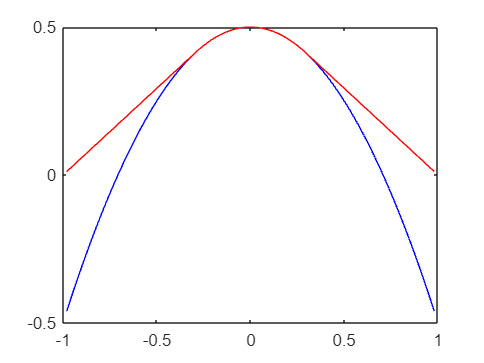

b_cap = - G*g; 

r = ones(m-1, 1);
x = zeros(m-1, 1);
y = ones(m-1, 1);
w_R = 1; 

for itr = 2 : ITR
    for i = 1 : m-1
        r(i) = b_cap(i) - 2*x(i); 

        if(i == 1) 
            r(i) = r(i) + x(i+1); 
        elseif(i == m-1)
            r(i) = r(i) + x(i-1); 
        else
            r(i) = r(i) + x(i-1) + x(i+1); 
        end
        
        prev_x = x(i); 
        x(i) = max(0, prev_x + w_R*r(i)/2); 
        y(i) = -r(i) + 2*(x(i) - prev_x); 
    end
end

w = g + x;

plot(x_step, g, 'b'), hold on
plot(x_step, w, 'r'), hold off; 

function y = func_g(x)
    y = 0.5 - x.*x; 
end